clear all
close all
rng(1);
% load simdata
load DATA_EMPS
qg=(qg*4);

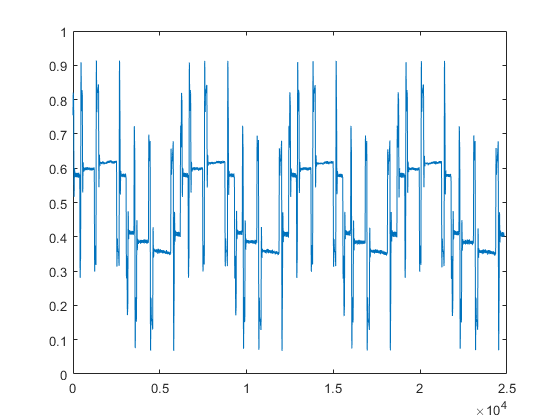


u = (vir+5)/10;
y = (qm*4);

% y = qm;
% qm = qm+0.001*randn(size(qm))
% y = y+0.005*randn(size(y))
plot(u)

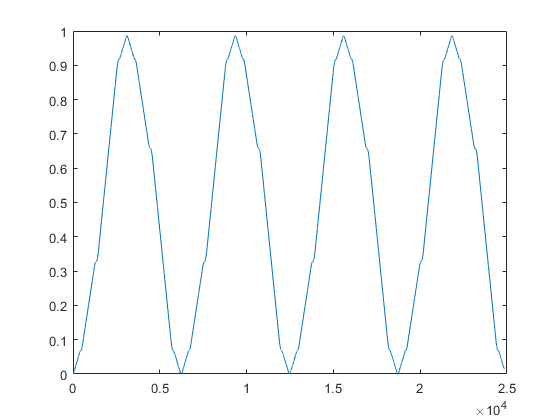

plot(y)

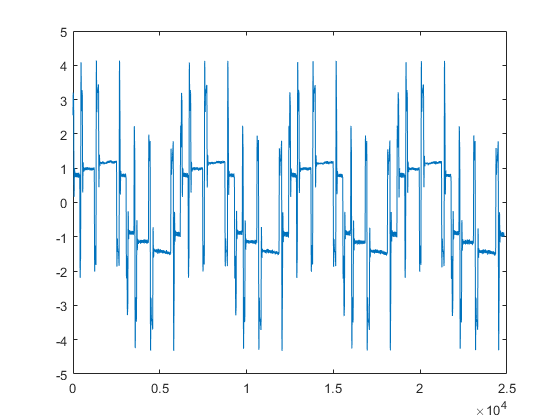

plot(vir)



min(u)

ans = 0.0674

min(y)

ans = -8.8000e-05

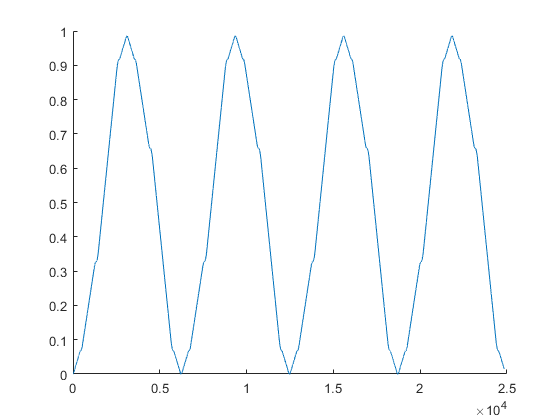


y(y<0)=0;
figure;
hold on
% plot(u(:,1))
plot(y(:,1))
hold off

m = 20

m = 20

u4 = u(1:13000+1);
u3 = u((m*1+1):((m*1)+13000+1));
u2 = u((m*2+1):((m*2)+13000+1));
u1 = u((m*3+1):((m*3)+13000+1));
y1 = y((m*3+1):((m*3)+13000+1));
y2 = y((m*2+1):((m*2)+13000+1));
y3 = y((m*1+1):((m*1)+13000+1));
y4 = y(1:13000+1);

featurez= [u4 u3 u2 u1 y1 y2 y3 y4];
min(featurez)

ans =     0.0674    0.0674    0.0674    0.0674         0         0         0         0


zeta = y((m*4):((m*4)+13000));

u4t = u(14000:end-4*m);
u3t = u((14000+1*m):(end-3*m));
u2t = u((14000+2*m):(end-2*m));
u1t = u((14000+3*m):(end-1*m));
y1t = y((14000+3*m):(end-1*m));
y2t = y((14000+2*m):(end-2*m));
y3t = y((14000+1*m):(end-3*m));
y4t = y(14000:end-4*m);

tfeaturez= [u4t u3t u2t u1t y1t y2t y3t y4t];

tlabels = y((14000+4*m):(end));
refer = qg((14000+4*m):(end));

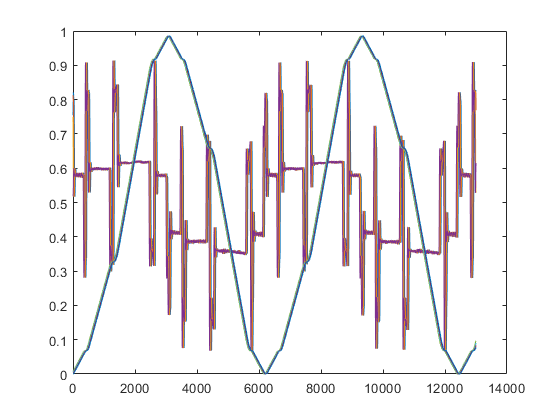

plot(featurez)

clear u y

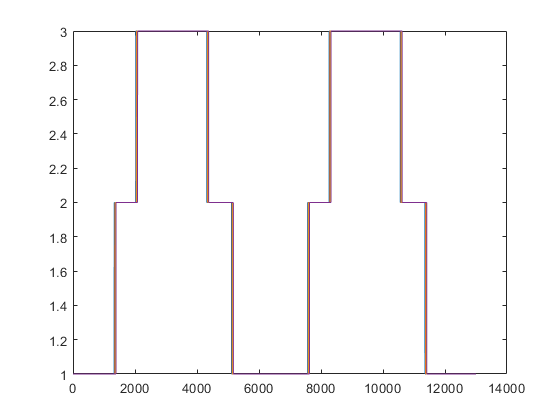

[N, d]=size(featurez); 

nn = 2;  %degree B-spline
knotintervals = 3;
nnn= knotintervals+nn;

bs = bspline([0:nn+1]);
M = flipud(bs.coefs)';

knotdist = 1/knotintervals;

indexes = floor(featurez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

plot(indexes(:,5:8))


inputs = (featurez/knotdist)-indexes+1;
for i=1:d
bn = inputs(:,i).^[nn:-1:0]*M;

u{i} = zeros(N,nnn);
for ii=1:N
   u{i}(ii,indexes(ii,i):indexes(ii,i)+nn) = bn(ii,:);
end
end



Pcount = (nnn)^d

Pcount = 390625

% gamma=((N/Pcount^4))
% gamma=0

R = nnn^2;
R=8;
r=R*ones(1,d+1);

% %  r(d-1)=nnn^2;
r(1) = 1;   r(d+1)=1;
r(2)=nnn;  r(d)=nnn;

disp(r)

     1     5     8     8     8     8     8     5     1



n=nnn*ones(1,d);

init=cell(1,d);
    for i=1:d
        init{i}.core=randn(r(i),n(i),r(i+1));
        init{i}.core=(init{i}.core/(norm(init{i}.core(:))));
        init{i}.r(1)=r(i);
        init{i}.n = n(i);
        init{i}.r(2)=r(i+1);
    end


   
    
% function TN=tencom(y,u,r,init,varargin)

% 2018, Ching-Yun KO

% N=size(u{1},1);
% d=size(u,2);                 

for i=1:d
    n(i)=size(u{i},2);
end
  

for i=1:d
    TN.core{i}=init{i}.core;
    TN.n(i,:)=[init{i}.r(1),init{i}.n,init{i}.r(2)];
end


Vp=cell(1,d);
Vm=cell(1,d);

Vm{1}=ones(N,1);
Vp{d}=ones(N,1);

% initialize right-orthonormal cores with prescribed TN ranks
for i=d:-1:2
    Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
end

difforder=2

difforder = 2

P = diff(eye(nnn),difforder);
PP = P'*P;

res1=[];
res2=[];
MAXITR = d;

itr=1;                          % counts number of iterations
ltr=1;                          % flag that checks whether we sweep left to right
sweepindex=1;                   % index that indicates which TT core will be updated

gamma=0.01;
 tic
bbb=1;
% while itr<2 || ((e(itr) < e(itr-1)) && (itr < MAXITR) && e(itr) > THRESHOLD)
while itr<2 ||  (itr < MAXITR )
%     ---------------------updateTT-----------------;
            
nselect = floor(((itr+1)/MAXITR)^4*(N));
dataselect = randperm((N),nselect);
dataselect = 1:N;
    %         % first construct the linear subsystem matrix
        A=dotkron(Vm{sweepindex}(dataselect,:),u{sweepindex}(dataselect,:),Vp{sweepindex}(dataselect,:));
%         g=pinv(A'*A)*(A'*y(dataselect,:));
     
%        
                   
%         -------------------difference penalty 
        for j=1:d
        Csize = TN.n(j,:);
        
        Dm = reshape(permute(TN.core{j}, [2 1 3]), [Csize(2) Csize(1)*Csize(3)]);
        mDDm = reshape(Dm'*Dm, [Csize(1) Csize(3) Csize(1) Csize(3)]);
        DD{j} = reshape(permute(mDDm,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        PD = P*Dm;
        DPPD = reshape(PD'*PD, [Csize(1) Csize(3) Csize(1) Csize(3)]);
        DWD{j} = reshape(permute(DPPD,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        eyez{j}= reshape(eye(Csize(1)), [Csize(1)^2 1]);
        eyep{j}= reshape(eye(Csize(2)), [Csize(2)^2 1]);
        end
        eyez{d+1}=1;
        
        for p= 1:d
            Dsize = TN.n(sweepindex,:);   
                if sweepindex==p
                    D1 = eyez{sweepindex};
                    D2 = PP(:);
                    D3 = eyez{sweepindex+1};
                elseif sweepindex<p
                    D1 = eyez{sweepindex};  
                    D2 = eyep{sweepindex};   
                    D3= DWD{p}*eyez{p+1};           
                    for it=(p-1):-1:(sweepindex+1)               
                        D3 = DD{it}*D3;
                    end                               
                elseif sweepindex>p   
                    D1= eyez{p}'*DWD{p};
                    for it=(p+1):(sweepindex-1)               
                        D1 = D1*DD{it};
                    end
                    D1=D1';
                    D2 = eyep{sweepindex};   
                    D3= eyez{sweepindex+1}; 
                end
          
            WW = kron(D3, kron(D2, D1));
            Wtemp = permute(reshape(WW, [Dsize(1) Dsize(1) Dsize(2) Dsize(2) Dsize(3) Dsize(3)]), [1 3 5 2 4 6]);
            W{p} = reshape(Wtemp, [prod(Dsize) prod(Dsize)]); 
        end
        WWW = W{1};
        for s =2:d
            WWW = WWW + W{s};
        end
%         ----------------------- 
        D = eye(r(sweepindex)*(n(sweepindex))*r(sweepindex+1));         

        g=pinv(A'*A + gamma*WWW)*(A'*zeta(dataselect,:));

        if ltr
            % left-to-right sweep, generate left orthogonal cores and update vk1
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex)*(n(sweepindex)),r(sweepindex+1)])); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex+1)),[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex+1}=reshape(R(1:r(sweepindex+1),:)*reshape(TN.core{sweepindex+1},[r(sweepindex+1),(n(sweepindex+1))*r(sweepindex+2)]),[r(sweepindex+1),n(sweepindex+1),r(sweepindex+2)]);
            Vm{sweepindex+1}=dotkron(Vm{sweepindex},u{sweepindex})*reshape(TN.core{sweepindex},[r(sweepindex)*n(sweepindex),r(sweepindex+1)]); % N x r_{i}
        else
            % right-to-left sweep, generate right orthogonal cores and update vk2
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex),(n(sweepindex))*r(sweepindex+1)])'); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex))',[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex-1}=reshape(reshape(TN.core{sweepindex-1},[r(sweepindex-1)*(n(sweepindex-1)),r(sweepindex)])*R(1:r(sweepindex),:)',[r(sweepindex-1),n(sweepindex-1),r(sweepindex)]);
            Vp{sweepindex-1}=dotkron(Vp{sweepindex},u{sweepindex})*reshape(permute(TN.core{sweepindex},[3 2 1]),[r(sweepindex+1)*n(sweepindex),r(sweepindex)]); % N x r_{i-1}    

        end
    
   %     ---------------------updatesweep-----------------; 
     
                if ltr
                    sweepindex=sweepindex+1;
                    if sweepindex== d                
                        ltr=0;
                        timer=toc;
                    end
                else
                    sweepindex=sweepindex-1;
                    if sweepindex== 1                
                        ltr=1;
                        timer=toc;
                    end
                end
    
    
        % only check residual after 1 half sweep
        if (sweepindex==d) || (sweepindex==1) % half a sweep
            
            res1(itr)=norm(A*g-zeta(dataselect,:))^2/(nselect); % check residual
            res2(itr)=1*(g'*g);
           
            if (itr>4)
%                 if (res1(itr)<1) || (abs(res1(itr)-res1(itr-2))<1)
%                  disp(res1(itr))
%                  break;
%                  end
            end
            
            itr=itr+1; %update iteration
            
            disp(["iteration:" itr timer])
        end   

        
end  

    "iteration:"    "2"    "0.42657"

    "iteration:"    "3"    "0.85911"

    "iteration:"    "4"    "1.1886"

    "iteration:"    "5"    "1.6059"

    "iteration:"    "6"    "2.0879"

    "iteration:"    "7"    "2.4515"

    "iteration:"    "8"    "2.7911"



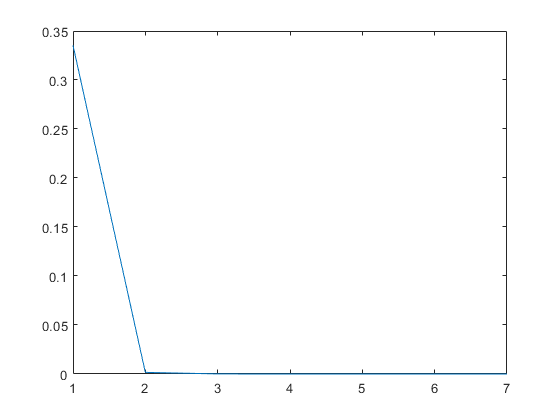

plot(res1)

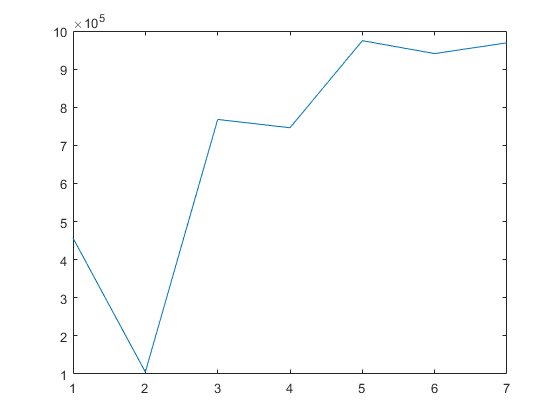

plot(res2)


[Nt, dt]=size(tfeaturez);

indexes = floor(tfeaturez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (tfeaturez/knotdist)-indexes+1;

for i=1:dt
bn = inputs(:,i).^[nn:-1:0]*M;

ut{i} = zeros(Nt,nnn);
for ii=1:Nt
   ut{i}(ii,indexes(ii,i):indexes(ii,i)+nn) = bn(ii,:);
end
end

% [N, d]=size(featurez);

output=zeros(Nt,1);

G = TN.core;

for i = 1:length(G)
Gsize = [Nt size(G{i},1)  size(G{i},3)];
tempz = reshape(ut{i}*unfold(G{i},2), Gsize);
V{i} = permute(tempz, [2 3 1]);
end


for jj=1:Nt   
f = (V{1});
f=1;
for i = 1:length(G)
f = f*V{i}(:,:,jj);
end
output(jj)=f';
end



% [tlabelz, id] = sort(tlabels);
tlabelz = tlabels;
outputsrt = output;

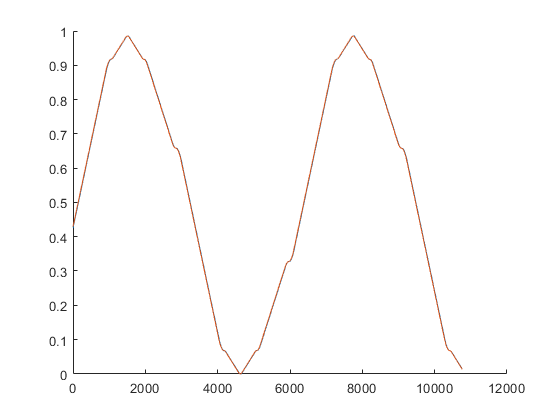


figure
hold on
plot(outputsrt)
% plot(tlabelz)
plot(refer)

hold off

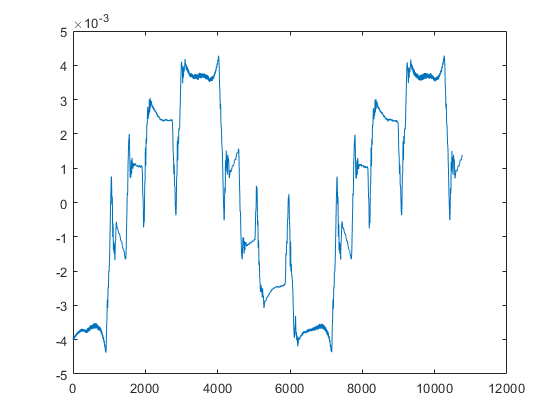

erboi = (outputsrt-refer);
plot(erboi)

pererror = sum(abs(erboi))/Nt

pererror = 0.0024

relerror = sum(abs(erboi)/sum(abs(refer)))

relerror = 0.0045

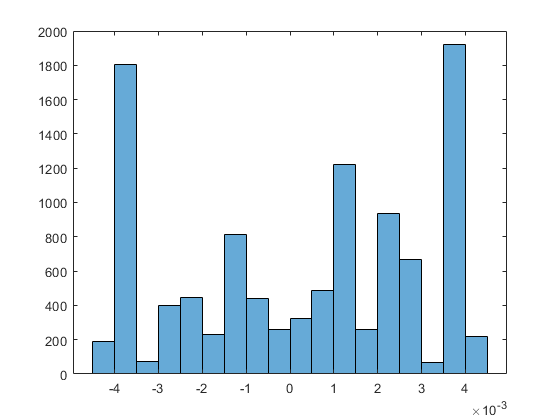

histogram((erboi)')


rerboi = (tlabelz-refer);
rpererror = sum(abs(rerboi))/Nt

rpererror = 0.0021


% ----------------- multistep aHEAD -------------------------
testfeatures=tfeaturez;
% testfeatures(:,1:4)=0.5
[Nt, dt]=size(tfeaturez);

for j = 200:Nt
feature = testfeatures(j,:);
feature(feature<0)= 0;
feature(feature>1)= 1;

indexes = floor(feature/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (feature/knotdist)-indexes+1;


for i=1:dt
    uz{i} = zeros(1,nnn);
bn = inputs(:,i).^[nn:-1:0]*M;
   uz{i}(indexes(i):indexes(i)+nn) = bn;
end

G = TN.core;

for i = 1:length(G)
Gsize = [size(G{i},1)  size(G{i},3)];
V{i} = reshape(uz{i}*unfold(G{i},2), Gsize);
end

f = (V{1});
f=1;
for i = 1:length(G)
f = f*V{i};
end
output(j)=f';

testfeatures(j+1*m,5)=output(j);
testfeatures(j+2*m,6)=output(j);
testfeatures(j+3*m,7)=output(j);
testfeatures(j+4*m,8)=output(j);
end

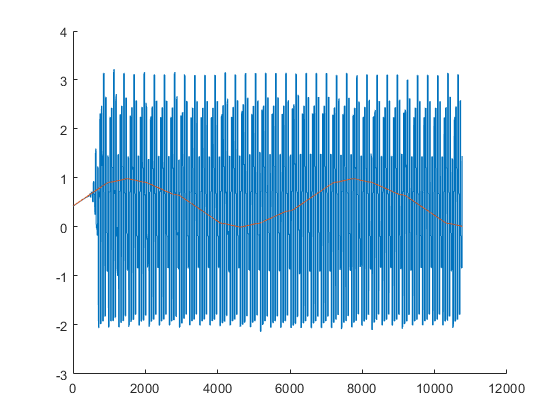


% smoothed= smoothdata(output,'sgolay',20); 
figure;
hold on
plot(output)
plot(refer)
% plot(smoothed)
hold off